## 1.8 更多二维绘图命令

1 errorbar    含误差条的线图

2 histogram 直方图

3 scatter      散点图

4 bar            柱状图

5 pie            饼图

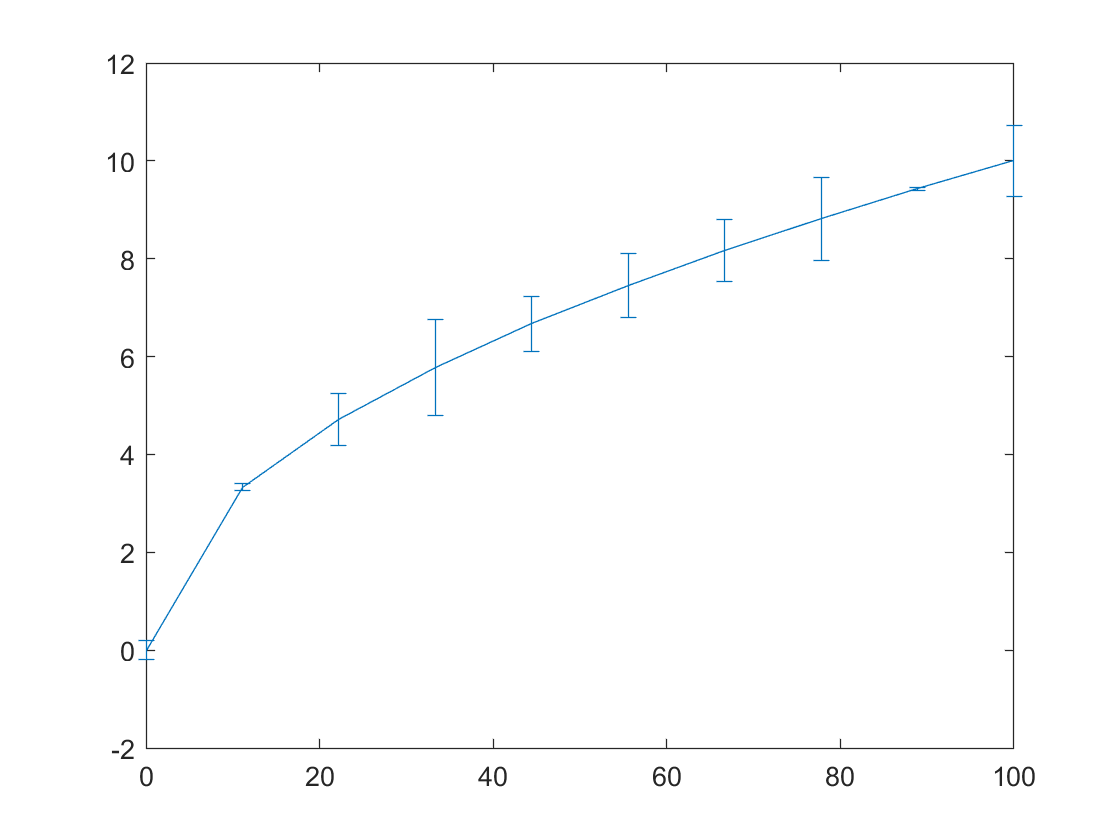

%errorbar(x,y,err) 绘制y对x的图，并且再每个数据点绘制一个垂直误差条

x = linspace(0,100,10);
y = x.^0.5;
err = rand(size(x));

errorbar(x,y,err);

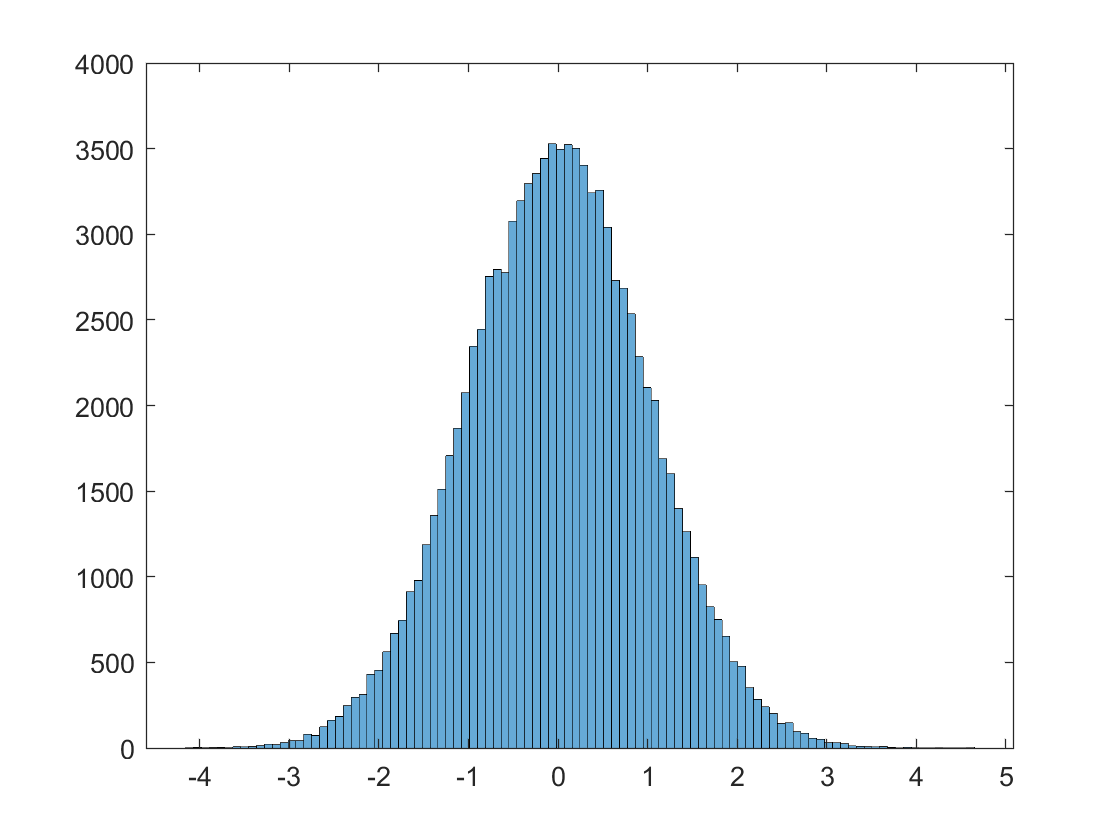

%histogram(x,n) 基于x创建直方图，n为区间数量

x = randn([1,100000]);
n = 100;
histogram(x,n);

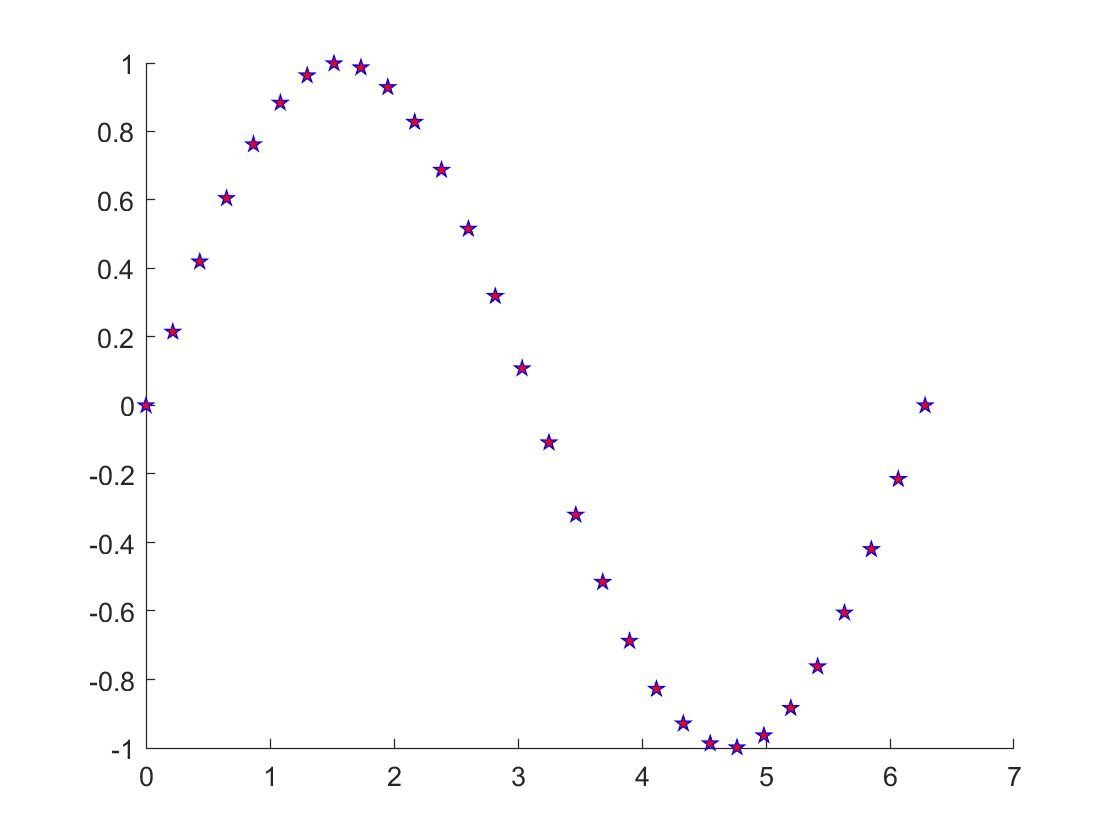

%散点图
% scatter(x,y)  在向量x与y指定位置创建一个包含圆形的散点图，跟plot很像，只是scatter是散点
%用法与plot很类似

x = linspace(0,2*pi,30);
y = sin(x);

scatter(x,y,'p','MarkerEdgeColor',"b","MarkerFaceColor","r");

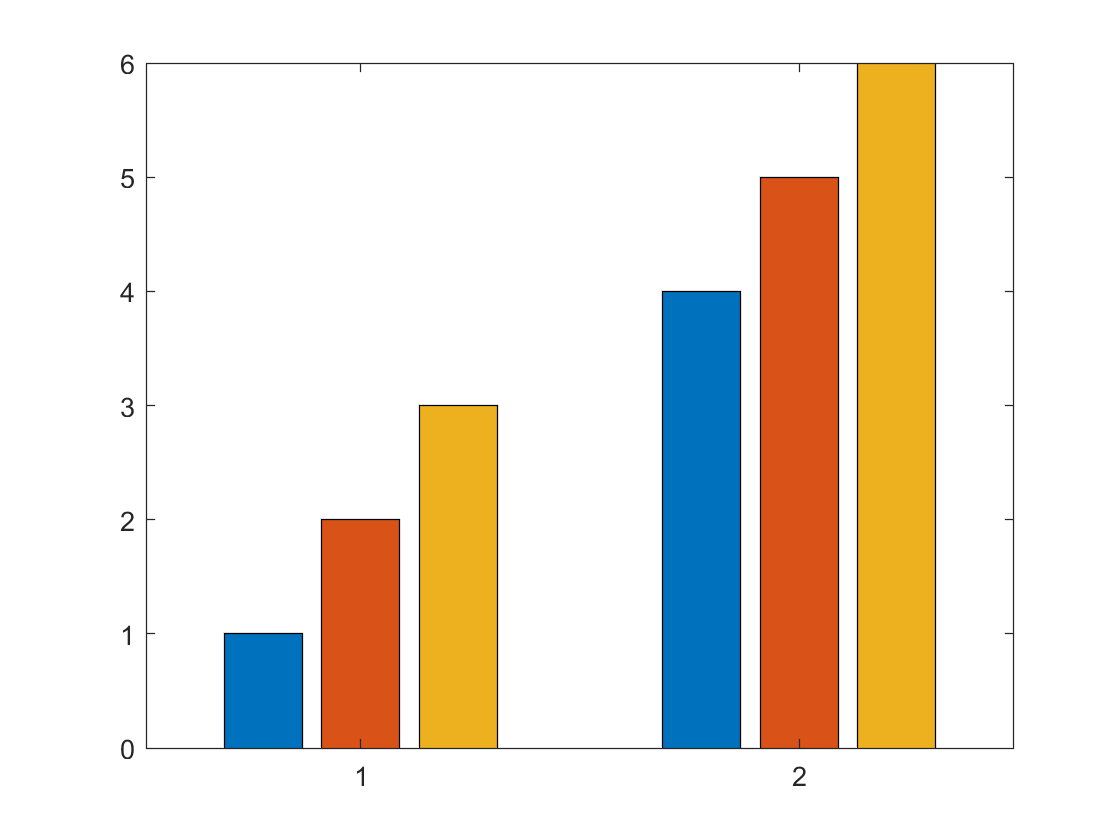

%bar(y) 创建一个条形图，y中的每个元素对应一个条形
%      如果y是m×n的矩阵， 则bar创建每组包n个条形的m个组

y = [1,2,3;
4,5,6];
bar(y);

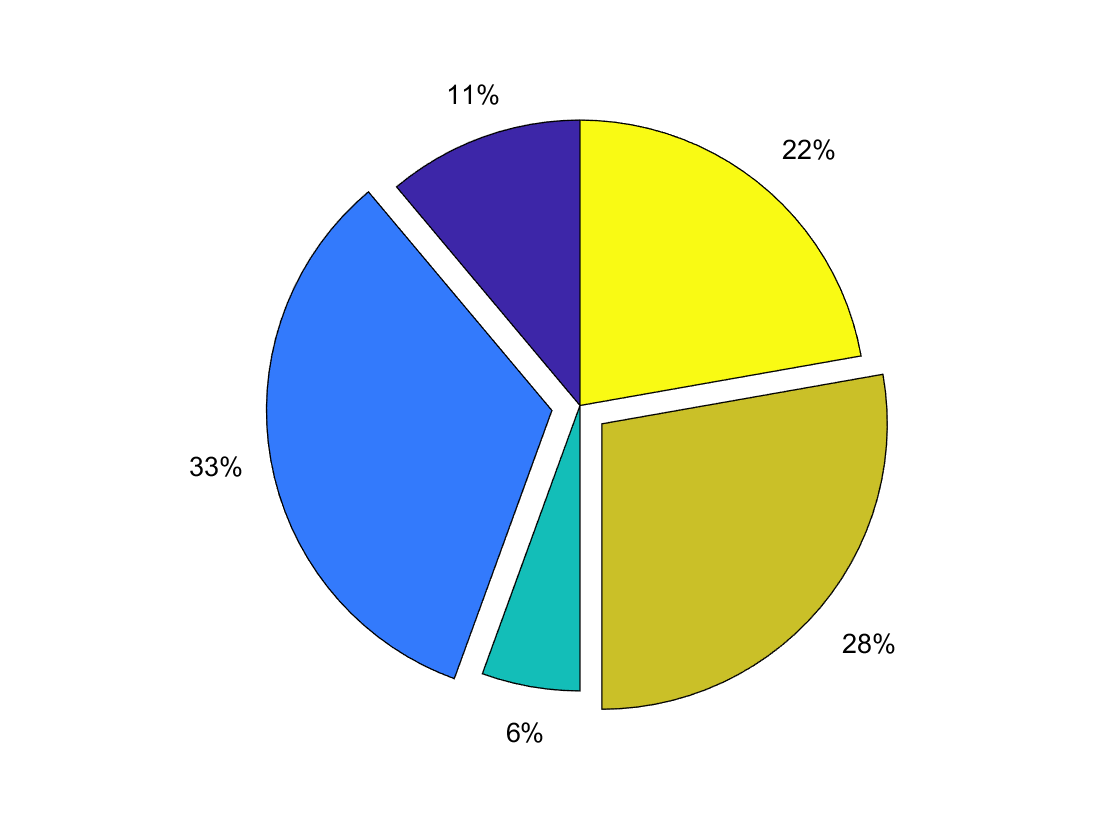

%pie(x,explode) 使用x中的数据绘制，图中的每一个区域代表x中的一个元素；
%           explode 将指定某个区域突出

x = [1 3 0.5 2.5 2];
% 是否弹出
explode = [0 1 0 1 0];

pie(x,explode);